warning off;

# PIV processing tool

This tool is made to process PIV pictures. It uses a singlepass filter, and it optionally can filter out bad data through means of moving averages, and the signal to noise ratio. An example is added in this folder, namely "example.tif". With this example, and example mask is also added, so that the airfoil and shadow regions can be masked out for the figures. The figure must have the convention that flow snapshot pairs are stacked above eachother forming 1 picture, as shown below. 

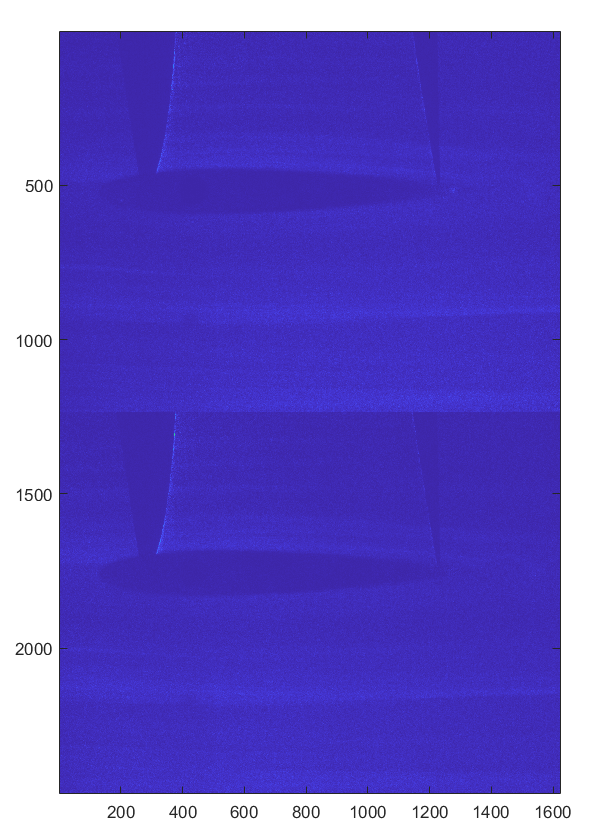

The tool requires you to input the picture width and height, as well as an origin point (x0,y0). Next to this you need to input your window size (this will be the moving correlation window), the pixel size, the magnification (M factor), and desired overlap. Overlap can increase the spacial resolution while maintaining the same amount of particles captured per correlation window. The dt is the time difference between the two snapshots. You can also add a Signal to Noise Ratio, but this is only relevant if you want to filter the signal. 

Beware! Filtering the signal costs significantly more time to process.


fileread ="example.tif";
foldread = '';
mask     = open("exampleMask.mat");
xlength  = 1624;
ylength  = 1236;
x0       = 125;      % x origin in pixels
y0       = 533;      % y origin in pixels


% additional parameters
ws       = 32;  
pix_size = 0.0044*10^3; %convert to micro meters
M        = 0.0534;      % Magnification factor
                         
ovlap    =0.5; 
dt       = 0.1*10^3; % convert to micro seconds
SNRmin   = 1.1;

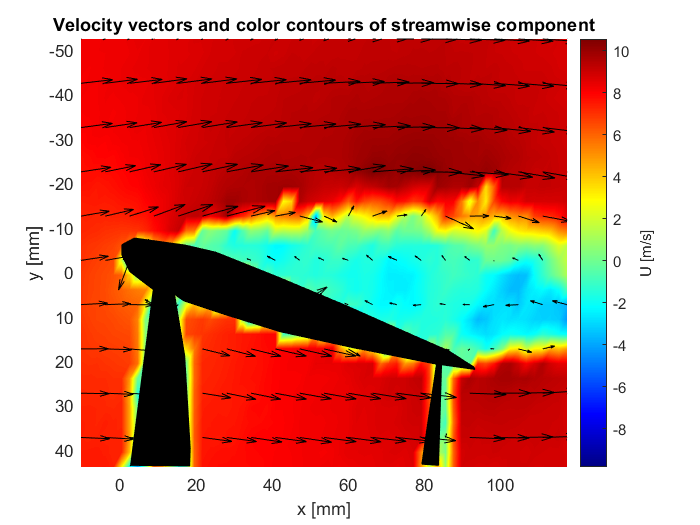


 filterSignal =false;

filestore  = 'test.dat';  %intermediate results are saved in here
plotpoints = 30;          %the amount of points in x and y direction
quivr      = 3;           %quiver ratio
im         = imread(fileread);



pivProcessor(foldread,filestore,fileread,ws,ovlap,dt,pix_size,...
             xlength,ylength,M,x0,y0,SNRmin, filterSignal);
         
         
res = plotdataField('', filestore,plotpoints,...
                     [mask.xmask,mask.ymask],quivr);